clear
clc

obj = CableStayedSuspension_Bridge;
% 定义主缆
main_cable_sectiondata = CircleSection(0.36/2); % 直径0.36m的圆截面
main_cable_materialdata = MaterialData_Cable; % 使用内置的 MaterialData_Cable的材料数据
Sec_cable = Section('主缆Cable',main_cable_sectiondata);
Mat_cable = Material('主缆Cable',main_cable_materialdata);
ET_cable = Link10;
CoordA_cable1 = [0,0,0]; % 左端点坐标
CoordB_cable1 = [690,10,50]; % 右端点坐标
L = 7.5+zeros(1,92); % 主缆X向分段，长度n=92
index_hanger = logical([zeros(1,24),repmat([1,0],1,22),zeros(1,23)]);% 吊杆会在主缆哪些位置悬吊，长度n-1=91，X正方向排列，与Cable.ForcePoint方向相同
weight = 5.9627e+08;
count_hanger = 22;
offset = [0,15,-110];
P_z = -weight/count_hanger/4; % 主跨加劲梁girder1的总重被主跨的StayedCable平分
P_h_z = [-6899011.28132516,-6954542.91481201,-6874409.69072045,-6867992.72670593,-7364810.07346540,...
         -7168591.42535053,-7148369.48016926,-6874013.86083734,-7353791.89155004,-7197287.28778477,...
         -7013593.60926663,-7123562.84447333,-7048052.35941508,-6827268.93097102,-6938357.73281755,...
         -6859353.84235700,-6900407.61013540,-6938382.37781615,-7058527.08554879,-6809440.28087538,...
         -7387457.42597635,-7415963.92910832];
P_h_y = [1618069.64794219,1628852.45509831,1401743.82000415,2172857.11690067,1548178.76538305,...
         1136968.61798086,2090283.67079187,1473179.55995348,1358259.28711548,1562862.61668075,...
         1091697.69679753,1159418.94207193,2289022.42681185,2236548.74592752,1744340.29156791,...
         1017376.24057047,1264980.09429775,1436212.89294877,2121810.49580236,949537.796062878,...
         1070947.85869782,1261912.60108965];
P_h_x = zeros(size(P_h_z));
Z_Om = -100; % 主缆跨中点Z
obj.Params.P_girder_z_MainSpan = P_h_z;
tic
[cable1,Output_MS] = obj.buildMainSpanCable(CoordA_cable1,CoordB_cable1,L,index_hanger,P_h_x,P_h_y,P_h_z,Z_Om,Sec_cable,Mat_cable,ET_cable);
toc

历时 0.072033 秒。


maincable = obj.StructureList{1};

% 提取主缆从左端点到第1个吊点范围内的的所有计算点及其坐标
num_CalculatePoint = 24;
CalculatePoint = maincable.Point(2:25);
X_CalculatePoint = [CalculatePoint.X];
Y_CalculatePoint = [CalculatePoint.Y];
Z_CalculatePoint = [CalculatePoint.Z];
PointA = maincable.PointA;

对于


$$z=c_i \cosh \left(\frac{x}{c_i \cos \alpha_i}+a_i\right)-c_i \cosh a_i$$


% 假如不设置这些计算点，仅通过左端点和第1个吊点的坐标，根据悬链线公式，计算这些计算点位置的[x,y,z]
Delta_x = X_CalculatePoint - PointA.X;

H_0     = maincable.Result_ShapeFinding.H(1);
alpha_0 = maincable.Result_ShapeFinding.alpha(1);
a_0     = maincable.Result_ShapeFinding.a(1);
c_0     = -H_0/maincable.Params.q;

H       = H_0 + zeros(1,length(X_CalculatePoint));
alpha   = alpha_0 + zeros(size(H));
a       = a_0 + Delta_x/(c_0*cos(alpha_0));

y = PointA.Y - Delta_x* tan(alpha_0)

y =     0.9304    1.8607    2.7911    3.7214    4.6518    5.5821    6.5125    7.4428    8.3732    9.3036   10.2339   11.1643   12.0946   13.0250   13.9553   14.8857   15.8160   16.7464   17.6767   18.6071   19.5375   20.4678   21.3982   22.3285


z = PointA.Z - c_0.* cosh(Delta_x./(c_0.*cos(alpha_0)) + a_0) + c_0.*cosh(a_0)

z =    -3.0694   -6.1359   -9.1995  -12.2601  -15.3178  -18.3726  -21.4245  -24.4734  -27.5194  -30.5624  -33.6026  -36.6398  -39.6741  -42.7054  -45.7338  -48.7593  -51.7819  -54.8016  -57.8183  -60.8321  -63.8430  -66.8510  -69.8560  -72.8581


% 比较「悬链线计算方法」和「优化计算方法」得到的坐标
delta_z = z - Z_CalculatePoint

delta_z = 1.0e-03 *

   -0.0043   -0.0085   -0.0128   -0.0170   -0.0213   -0.0255   -0.0298   -0.0340   -0.0383   -0.0425   -0.0468   -0.0511   -0.0553   -0.0596   -0.0638   -0.0681   -0.0723   -0.0766   -0.0808   -0.0851   -0.0893   -0.0936   -0.0979   -0.1021


delta_y = y - Y_CalculatePoint

delta_y = 1.0e-03 *

    0.0089    0.0178    0.0268    0.0357    0.0446    0.0535    0.0624    0.0713    0.0803    0.0892    0.0981    0.1070    0.1159    0.1248    0.1338    0.1427    0.1516    0.1605    0.1694    0.1784    0.1873    0.1962    0.2051    0.2140


% 更改主缆线形求解代码
index = [false,maincable.Params.Index_Hanger,false];
num_Subcatenary = length(index)-1;% 92
num_Catenary = sum(index)+1;% 23
L_Subcatenary = maincable.Params.L;
L_Catenary = zeros(1,num_Catenary);
count_catenary = 1;
len_catenary = 0;
Index_CatenaryInSubcatenary = false(1,num_Subcatenary);
IndexCell_CatenaryInSubcatenary = cell(1,num_Catenary);
for i=1:length(index)
    if index(i) % 如果这里是吊点，就将长度赋值给L_Catenary(count)，然后重新计算长度
        % 释放累加的长度
        L_Catenary(count_catenary) = len_catenary;
        len_catenary = L_Subcatenary(i);
        % 
        IndexCell_CatenaryInSubcatenary{1,count_catenary} = Index_CatenaryInSubcatenary;
        Index_CatenaryInSubcatenary = false(1,num_Subcatenary);
        Index_CatenaryInSubcatenary(i) = true;
        %
        count_catenary = count_catenary + 1;
    elseif i==length(index)
        L_Catenary(count_catenary) = len_catenary;

        IndexCell_CatenaryInSubcatenary{count_catenary} = Index_CatenaryInSubcatenary;
    else % 如果这里不是吊点，就累加长度
        len_catenary = len_catenary + L_Subcatenary(i);
        Index_CatenaryInSubcatenary(i) = true;
    end
end

tic
maincable_clone = maincable.clone();
P_x = maincable_clone.Params.P_x;
P_y = maincable_clone.Params.P_y;
P_z = maincable_clone.Params.P_z;
maincable_clone.Algo_ShapeFinding.AlgoHandle = @Algo_Catenary3D_MainSpan_Faster;
maincable_clone.findShape(P_x,P_y,P_z);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       4    2.414759e+04    0.000e+00    2.092e+05
目标函数返回了 NaN；正在尝试一个新点...
    1      14    7.427008e+03    0.000e+00    9.317e+04    2.598e-01
目标函数返回了 NaN；正在尝试一个新点...
    2      24    4.011832e+03    0.000e+00    1.210e+04    6.495e-02
    3      37    3.983092e+03    0.000e+00    7.966e+03    1.421e-02
目标函数返回了 NaN；正在尝试一个新点...
    4      44    3.981613e+03    0.000e+00    8.869e+03    1.184e-02
    5      48    3.949260e+03    0.000e+00    5.518e+01    7.244e-03
    6      53    3.949259e+03    0.000e+00    2.790e+01    2.476e-05
    7      58    3.949259e+03    0.000e+00    1.390e+01    1.708e-05
    8      63    3.949258e+03    0.000e+00    6.707e+00    1.522e-05
    9      68    3.949258e+03    0.000e+00    3.322e+00    1.464e-05
   10      73    3.949258e+03    0.000e+00    2.119e+00    1.500e-05
   11      78    3.949258e+03    0.000e+00  

toc

历时 0.395871 秒。


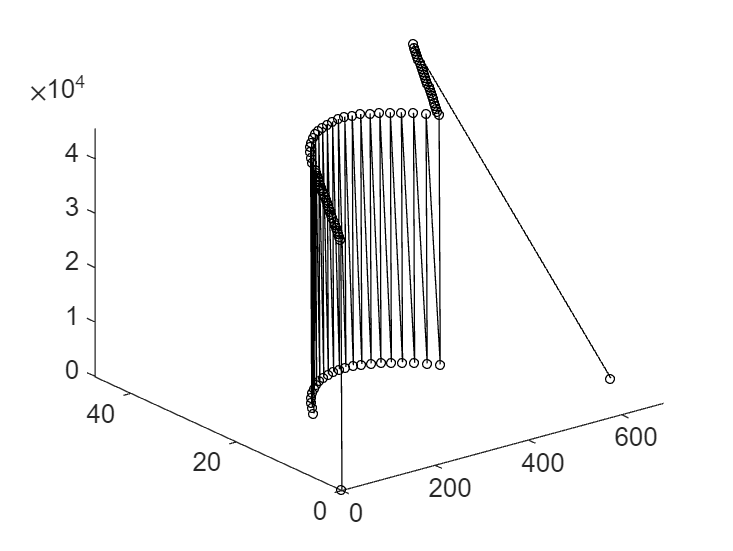

ans =   Scatter - 属性:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
          LineWidth: 0.5000
              XData: [0 7.5000 15 22.5000 30 37.5000 45 52.5000 60 67.5000 75 82.5000 90 97.5000 105 112.5000 120 127.5000 135 142.5000 150 157.5000 165 172.5000 180 187.5000 195 202.5000 210 217.5000 225 232.5000 240 247.5000 255 262.5000 270 … ]
              YData: [0 0.8751 1.7503 2.6254 3.5006 4.3757 5.2508 6.1260 7.0011 7.8763 8.7514 9.6265 10.5017 11.3768 12.2520 13.1271 14.0022 14.8774 15.7525 16.6277 17.5028 18.3779 19.2531 20.1282 21.0034 21.8785 22.7536 23.4839 24.3590 24.9434 … ]
              ZData: [0 4.5534e+04 4.5531e+04 4.5528e+04 4.5525e+04 4.5522e+04 4.5519e+04 4.5516e+04 4.5513e+04 4.5510e+04 4.5507e+04 4.5504e+04 4.5501e+04 4.5498e+04 4.5495e+04 4.5492e+04 4.5489e+04 4.5486e+04 4.5483e+04 4.5480e+04 4.5477e+04 … ]
           SizeData: 12
   

maincable_clone.plot


% x_p = [maincable.Point.X];
% y_p = [maincable.Point.Y];
% z_p = [maincable.Point.Z];
% x_pc = [maincable_clone.Point.X];
% y_pc = [maincable_clone.Point.Y];
% z_pc = [maincable_clone.Point.Z];
% y_p - y_pc
% z_p - z_pc

% H1 = maincable.Result_ShapeFinding.H
% H2 = maincable_clone.Result_ShapeFinding.H
% H1 - H2
% 
% a1 = maincable.Result_ShapeFinding.a
% a2 = maincable_clone.Result_ShapeFinding.a
% a1 - a2
% 
% alpha1 = maincable.Result_ShapeFinding.a
% alpha2 = maincable_clone.Result_ShapeFinding.a
% alpha1 - alpha2

cable_clone_hanger_point = maincable_clone.Point([false,maincable_clone.Params.Index_Hanger,false]);
cable_hanger_point = maincable.Point([false,maincable_clone.Params.Index_Hanger,false]);

[cable_hanger_point.Z] - [cable_clone_hanger_point.Z]

ans =    -0.3960   -0.4246   -0.4503   -0.4732   -0.4934   -0.5105   -0.5248   -0.5362   -0.5448   -0.5505   -0.5532   -0.5531   -0.5501   -0.5443   -0.5357   -0.5243   -0.5102   -0.4932   -0.4735   -0.4509   -0.4255   -0.3971
